#### Load Data (X_data, U_data)

%load TrainingData_M3v2_senoidal.mat
% X_sine=X_data;
% U_sine=U_data;
load Udata_M3_60.mat U_data
load Xdata_M3_60.mat X_data

load 

#### X_data - U_data Correlations

X_sine=X_data;
U_sine=U_data;

numTests = length(X_sine); % Número de tests
numStates = 4;            % Número de columnas en X_data (estados)
numInputs = 1;            % Número de columnas en U_data (variables manipuladas)

correlations = zeros(numTests, numStates, numInputs);

% Calcular la correlación entre X_data y U_data
for i = 1:numTests
    % Extraer las variables de X_data y U_data
    X = X_sine{i}.Variables; % Variables de estados (4 columnas)
    U = U_sine{i}.Variables; % Variables manipuladas (2 columnas)
    
    % Calcular correlación entre cada columna de X y U
    for j = 1:numStates
        for k = 1:numInputs
            correlations(i, j, k) = corr(X(:, j), U(:, k), 'Type', 'Pearson');
        end
    end
end

% Promediar las correlaciones a lo largo de todos los tests
meanCorrelations = mean(correlations, 1);
meanCorrelations=meanCorrelations';

% Mostrar la matriz de correlaciones promedio
disp('Mean correlation matrix between X (states) and U (actions):');

Mean correlation matrix between X (states) and U (actions):


meanCorrelations = squeeze(meanCorrelations); % Eliminar dimensiones redundantes
disp(meanCorrelations);

    0.0048
   -0.3548
    0.5984
    0.3983



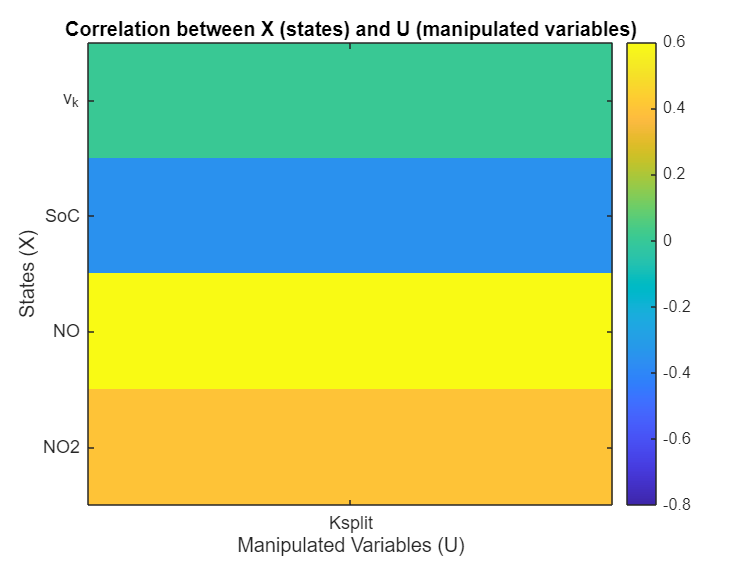


% Visualización gráfica
figure;
imagesc(meanCorrelations);
clim([-0.8 0.6]);         % Fijar el rango de colores
colorbar;
title('Correlation between X (states) and U (manipulated variables)');
xlabel('Manipulated Variables (U)');
ylabel('States (X)');
xticks(1:numInputs); xticklabels({'Ksplit'});
yticks(1:numStates); yticklabels({'v_k', 'SoC', 'NO', 'NO2'});

#### Load Markus' Data

%Model inputs with predictions
Test_full=readtable("Testdata_complete.xlsx",Sheet='Test_dataUnits',VariableNamingRule="preserve");
K_corr=Test_full.Ksplit;
vk_corr=Test_full.Velocity_kph;
GP_corr=Test_full.("Grade_%");
n_corr=Test_full.Engine_Speed_RPM;
PEM1_corr=Test_full.EM1_Power_kW;
PEM2_corr=Test_full.EM2_Power_kW;
minj_corr=Test_full.Injection_gps;
SoC_corr=Test_full.SoC_1;
NO_corr=Test_full.NO_kmolps;
NO2_corr=Test_full.NO2_kmolps;
torque_corr=Test_full.Shaft_Torque_Nm;

SoC_corr2=Test_full.SoC_1_pred;
NO_corr2=Test_full.NO_kmolps_pred;
NO2_corr2=Test_full.NO2_kmolps_pred;
torque_corr2=Test_full.Shaft_Torque_Nm_pred;

Inputs=[K_corr,vk_corr,GP_corr,n_corr,PEM1_corr,PEM2_corr,minj_corr];
%Preds=[SoC_corr,NO_corr,NO2_corr,torque_corr];
DCycle=[K_corr,vk_corr,GP_corr];
Inputs_mod=[n_corr,PEM1_corr,PEM2_corr,minj_corr];
Preds=[SoC_corr2,NO_corr2,NO2_corr2,torque_corr2];

#### Model Inputs vs. Outputs

numInputs = size(Inputs,2);
numPreds = size(Preds,2);            % Número de columnas en U_data (variables manipuladas)

correlations_IO = zeros(numPreds, numInputs);

    % Calcular correlación entre cada columna de X y U
    for j = 1:numPreds
        for k = 1:numInputs
            correlations_IO(j, k) = corr(Preds(:, j), Inputs(:, k), 'Type', 'Pearson');
        end
    end

% % Promediar las correlaciones a lo largo de todos los tests
% meanCorrelations_IO = mean(correlations_IO, 1);
% 
% % Mostrar la matriz de correlaciones promedio
% disp('Mean correlation matrix between X (states) and U (actions):');
% meanCorrelations_IO = squeeze(meanCorrelations_IO); % Eliminar dimensiones redundantes
% disp(meanCorrelations_IO);

% Visualización gráfica
figure;
imagesc(correlations_IO);
clim([-0.8 0.8]);
colorbar;
title('Correlation between Inputs and Predicted Outputs of the model');
xlabel('Inputs');
ylabel('Predicted Outputs');
xticks(1:numInputs); xticklabels({'K_{split}','v_k','GP','n_{ice}','P_{EM1}','P_{EM2}','m_{inj}'});
yticks(1:numPreds); yticklabels({'SoC', 'NO', 'NO_2','shaft torque'});

for j = 1:numPreds
    for k = 1:numInputs
        % Texto en cada celda del heatmap
        text(k, j, sprintf('%.2f', correlations_IO(j, k)), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle', ...
            'Color', 'k', 'FontSize', 10); % Color negro y tamaño de fuente ajustado
    end
end

#### Driving Cycle Parameters {v, GP, K} vs. Rest of Model Inputs

numInputs_mod = size(Inputs_mod,2);
numDcycle = size(DCycle,2);            % Número de columnas en U_data (variables manipuladas)

correlations_IO = zeros(numInputs_mod,numDcycle);

    % Calcular correlación entre cada columna de X y U
    for j = 1:numInputs_mod
        for k = 1:numDcycle
            correlations_DCI(j, k) = corr(DCycle(:, k), Inputs_mod(:, j), 'Type', 'Pearson');
        end
    end

% Visualización gráfica
figure;
imagesc(correlations_DCI);
clim([-0.8 0.8]);
colorbar;
title('Correlation between Driving Cycle parameters and Model Inputs');
xlabel('Driving Cycle Parameters');
ylabel('Model Inputs');
xticks(1:3); xticklabels({'K_{split}','v_k','GP'});
yticks(1:numInputs_mod); yticklabels({'n_{ice}','P_{EM1}','P_{EM2}','m_{inj}'});

% Agregar los valores en el heatmap
for j = 1:numInputs_mod
    for k = 1:numDcycle
        % Formato de texto en cada celda
        text(k, j, sprintf('%.2f', correlations_DCI(j, k)), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle', ...
            'Color', 'k', 'FontSize', 10);
    end
end